clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;

% 2.1 
eye(2);
G1 = FWT(1:2,1:2);
s = tf('s');
G = G1.C*inv((s*eye(5)-G1.A))*G1.B;
omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
    end
RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



% 2.5 
G=tf(FWT(1:2,1:2));

wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/10000; % desired disturbance attenuation inside bandwidth
M=3; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A])

Wp11 =
 
  0.3333 s + 1.885
  ----------------
   s + 0.0001885
 
Continuous-time transfer function.



Wp=[Wp11 0; 0 wB2] %

Wp =
 
  From input 1 to output...
       0.3333 s + 1.885
   1:  ----------------
        s + 0.0001885
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
Continuous-time transfer function.




% Control weights
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []




Plant=augw(G,Wp,Wu,[]) % build plant

Plant =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1   -0.0001885           0           0      0.1598    0.001658      0.4338   -0.006493
   x2            0     -0.0014   -0.001024           0           0           0           0
   x3            0   0.0009766           0           0           0           0           0
   x4            0           0           0     -0.5979      -2.744      -1.177      -0.271
   x5            0           0           0           4           0           0           0
   x6            0           0           0           0           1           0           0
   x7            0           0           0           0           0         0.5           0
   x8            0           0           0           0           0           0        0.25
   x9            0           0           0           0           0           0           0
   x10           0           0           0           0           0       

P=minreal(Plant) % to check number of states

5 states removed.

P =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.2542    0.01037     0.0467     -1.183     0.7419     0.2764    0.05737     0.0809
   x2      0.406   -0.04018   -0.01065     0.1624    -0.4212    0.02059   -0.03215   -0.01831
   x3  -0.009303     0.2577   -0.01156    -0.1082     0.1401   -0.03529    0.05568  -0.002812
   x4     0.4283    -0.3171     0.1516    -0.1668       -3.6     -1.245    -0.4001    -0.3966
   x5     -1.248     -0.118    -0.3571      2.404    -0.3779    -0.3885   -0.02829    -0.1212
   x6    -0.6088   -0.04575    -0.1488     0.4175     -0.187    -0.2818   -0.02759   -0.08366
   x7    -0.1719   -0.04049    -0.0747      0.201    -0.2057    -0.1278   -0.02487   -0.04576
   x8     0.2264    0.03512    0.08107     0.2642    0.05619     0.1472    0.01703    0.04939
 
  B = 
                ?           ?  Beta (deg)  tau_e (Nm)
   x1     0.05657           0    -0.07384     0.01122
   x2

% 2.7

[K2,CL2,GAM2,INFO2] = hinfsyn(P,2,2)

K2 =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1    37.73   -8.093   -17.57    7.307     19.4   -47.45   -53.03    149.2
   x2    -35.3    7.772    18.36   -7.923   -17.59    44.55    52.03     -147
   x3    13.68   -2.691   -6.512    2.991    6.894   -17.24   -19.34    54.57
   x4   -23.22    4.845     12.1   -5.523   -15.06    28.38    33.88   -97.07
   x5   -264.1    56.88    126.4   -57.13     -130    332.2    375.2    -1056
   x6   -98.91    21.37    48.59   -21.85    -48.2    123.6    141.7   -399.2
   x7    46.64   -10.65   -30.46    10.79    19.95   -54.78   -74.16    211.8
   x8   -4.584   0.8446  -0.3081  -0.8181   -3.149    6.869    4.054   -10.43
 
  B = 
               u1          u2
   x1     0.05657  -4.754e-17
   x2     0.01828   6.086e-17
   x3     -0.1752   9.684e-17
   x4    0.005088  -4.566e-18
   x5     0.03053  -1.517e-17
   x6     -0.2792     2.8e-17
   x7     -0.3099  -8.028e-18
   x8      0.8893   1.107e-17
 
  C

GAM2 = 0.6107

INFO2 =   hinfINFO with properties:

    gamma: 0.6107
        X: [8×8 double]
        Y: [8×8 double]
       Ku: [2×8 double]
       Kw: [2×8 double]
       Lx: [8×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]



%Nyquist plot
LoopT=G*K2+eye(2);
PolesL=pole(minreal(LoopT));

10 states removed.


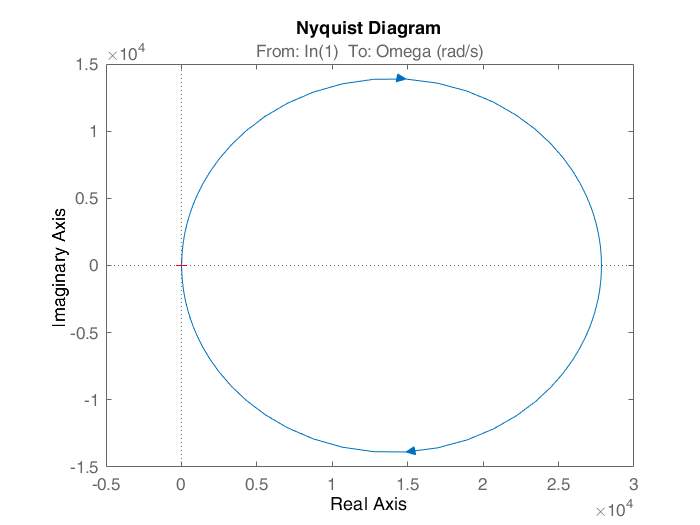

nyqDet=LoopT(1,1)*LoopT(2,2)-LoopT(1,2)*LoopT(2,1);
nyquist(nyqDet)

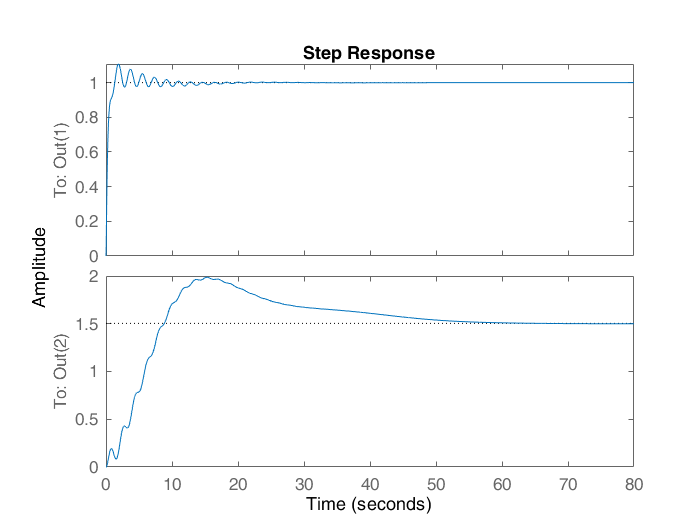

% 2.8 

% Calculate S and T
Sens=(1/Wp)*CL2(1:2,1:2);
Compl=eye(2)-Sens;

% Step in reference
step(Compl(1:2,1))

stepinfo(Compl(1:2,1))

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


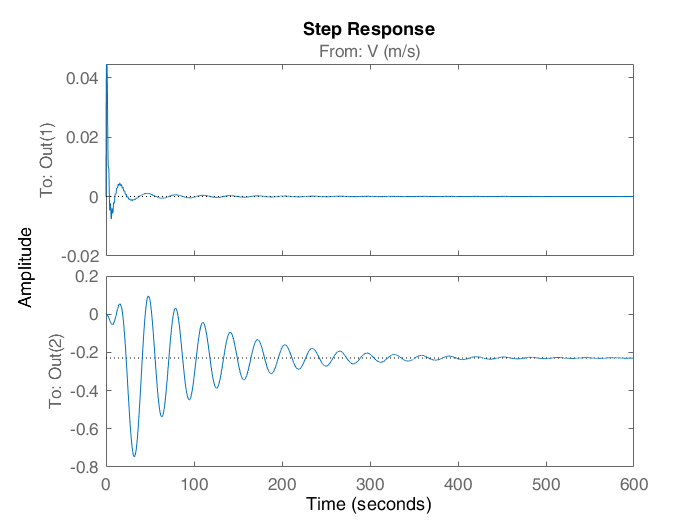



% Plot influence of step in disturbance
D_rej=Sens*FWT(1:2,3);
step(D_rej)

stepinfo(D_rej)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime
